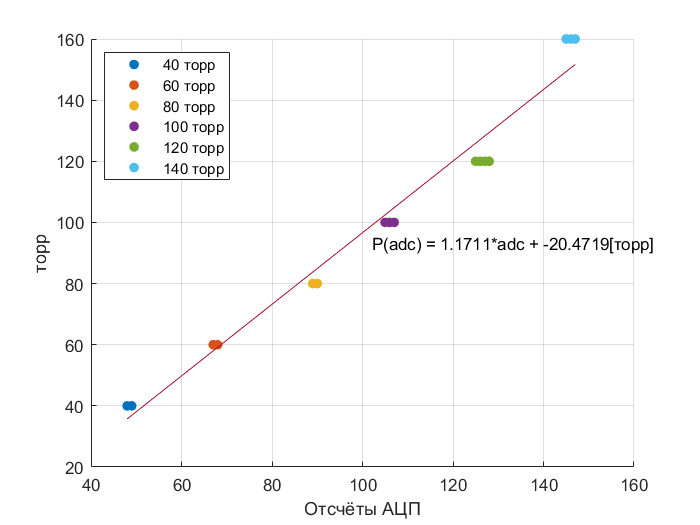

close all;
clear valuables;




%Калибровка
c40 = importdata("calibration_1.txt");
c60 = importdata("calibration_2.txt");
c80 = importdata("calibration_3.txt");
c100 = importdata("calibration_4.txt");
c120 = importdata("calibration_5.txt");
c140 = importdata("calibration_6.txt");

fclose('all');

torr40 = ones(length(c40), 1)*40;
torr60 = ones(length(c60), 1)*60;
torr80 = ones(length(c80), 1)*80;
torr100 = ones(length(c100), 1)*100;
torr120 = ones(length(c120), 1)*120;
torr140 = ones(length(c140), 1)*160;

Adc = [c40; c60; c80; c100; c120; c140];
torr = [torr40; torr60; torr80; torr100; torr120; torr140];
c = polyfit(Adc, torr, 1);

cFigure = figure('Name','Калибровка', "NumberTitle",'off');
hold all;
plot(c40, torr40, '.', 'MarkerSize',20);
plot(c60, torr60, '.', 'MarkerSize',20);
plot(c80, torr80, '.', 'MarkerSize',20);
plot(c100, torr100, '.', 'MarkerSize',20);
plot(c120, torr120, '.', 'MarkerSize',20);
plot(c140, torr140, '.', 'MarkerSize',20);

plot(Adc, polyval(c, Adc));
legend('40 торр','60 торр','80 торр','100 торр','120 торр','140 торр', 'Location','northwest');
grid on;
xlabel('Отсчёты АЦП');
ylabel('торр');
text(mean(Adc)*1.05, mean(torr), ['P(adc) = ', num2str(c(1)) , '*adc + ', num2str(c(2)), '[торр]']);
set(gcf, 'Visible', 'on');
saveas(cFigure, 'Калибровка.png');

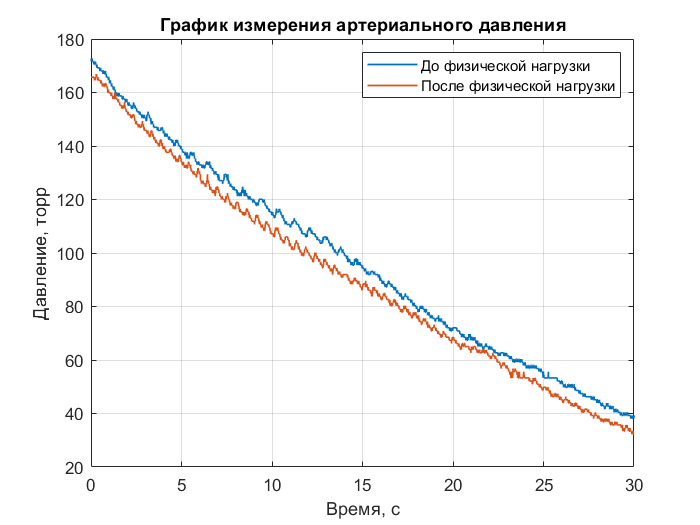




%Давление
dt = 0.01;
adcBefore = fscanf(fopen('data_before.txt'), '%d');
tBefore = linspace(0, length(adcBefore)*dt, length(adcBefore));
pBefore = polyval(c, adcBefore);

adcAfter = fscanf(fopen('data_after.txt'), '%d');
tAfter = linspace(0, length(adcAfter)*dt, length(adcAfter));
pAfter = polyval(c, adcAfter);

pFigure = figure('Name','Графики зависимости давления от времени', 'NumberTitle',"off");

plot(tBefore, pBefore, tAfter,pAfter, 'Linewidth',  1);
legend('До физической нагрузки', 'После физической нагрузки');

grid on;
xlim([0,30]);

xlabel('Время, с');
ylabel('Давление, торр');
title('График измерения артериального давления');
set(gcf, 'Visible', 'on');

saveas(pFigure, 'Давление.png');

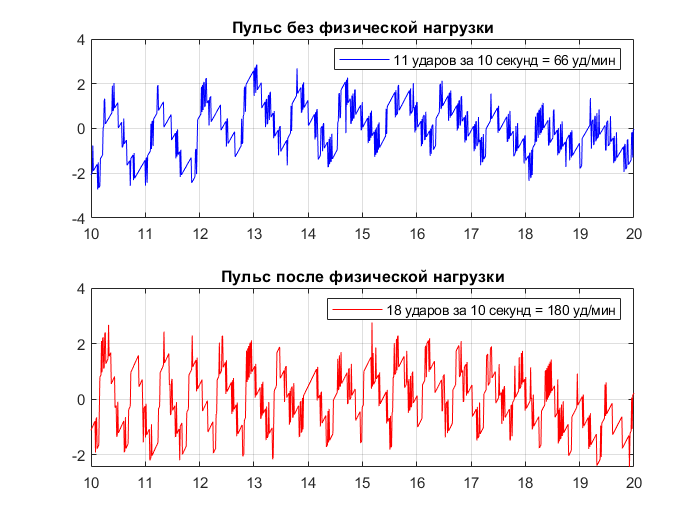



%Обработка

cBefore = polyfit(tBefore, pBefore, 7);
cAfter = polyfit(tAfter, pAfter, 5);
pulseBefore = pBefore - polyval(cBefore, tBefore)';
pulseAfter = pAfter - polyval(cAfter, tAfter)';

pulseFigure = figure('Name','Графики пульса', "NumberTitle","off");

subplot(2,1,1);

plot(tBefore, pulseBefore, 'b');
legend('11 ударов за 10 секунд = 66 уд/мин');
grid on;
xlim([10, 20]);
title('Пульс без физической нагрузки');
set(gcf, 'Visible', 'on');

subplot(2,1,2);

plot(tAfter, pulseAfter, 'r');
legend('18 ударов за 10 секунд = 180 уд/мин');
grid on;
xlim([10, 20]);
title('Пульс после физической нагрузки');
set(gcf, 'Visible', 'on');
saveas(pulseFigure, 'Пульс.png')